clear all
close all
load("D:\V1_Cortex_Paper\MultichannelDataTanks\Layer5_Sig_MS.mat")
load("D:\V1_Cortex_Paper\MultichannelDataTanks\Layer6_Sig_MS.mat")

DEV_R = [Layer5_Sig.DEV1;Layer5_Sig.DEV2];
STD_R = [Layer5_Sig.STD1;Layer5_Sig.STD2];
CTR_R = [Layer5_Sig.CTR1MS;Layer5_Sig.CTR2MS];

DEV_P = [Layer5_Sig.NormDEVPms1;Layer5_Sig.NormDEVPms2];
STD_P = [Layer5_Sig.NormSTDPms1;Layer5_Sig.NormSTDPms2];
CTR_P = [Layer5_Sig.CTR1MS;Layer5_Sig.CTR2MS];

y_R = [DEV_R, CTR_R, STD_R];
y_P = [DEV_P, CTR_P, STD_P];


y_mR = mean(y_R,'omitnan')

y_mR =     0.7305    0.1755    0.1310



y_mP = mean(y_P,'omitnan')

y_mP =     1.0747    0.1755    0.2291



y = [y_mR; y_mP];

b = bar(y, 'grouped');
ylim([0 1.2]);

hold on
xline(0,'LineWidth',2);
ylabel('Normalized spike count')

RNDEV_std = std(y_R(:,1),'omitnan');
err_RNDEV = RNDEV_std / sqrt(size(y_R(:,1),1))

err_RNDEV = 0.0375


RNCTR_std = std(y_R(:,2),'omitnan');
err_RNCTR = RNCTR_std / sqrt(size(y_R(:,2),1))

err_RNCTR = 0.0060


RNSTD_std = std(y_R(:,3),'omitnan');
err_RNSTD = RNSTD_std / sqrt(size(y_R(:,3),1))

err_RNSTD = 0.0077


PNDEV_std = std(y_P(:,1),'omitnan');
err_PNDEV = PNDEV_std / sqrt(size(y_P(:,1),1))

err_PNDEV = 0.0331


PNCTR_std = std(y_P(:,2),'omitnan');
err_PNCTR = PNCTR_std / sqrt(size(y_P(:,2),1))

err_PNCTR = 0.0060


PNSTD_std = std(y_P(:,3),'omitnan');
err_PNSTD = PNSTD_std / sqrt(size(y_P(:,3),1))

err_PNSTD = 0.0188


y_mRerr = [err_RNDEV err_RNCTR err_RNSTD]

y_mRerr =     0.0375    0.0060    0.0077


y_mPerr = [err_PNDEV  err_PNCTR err_PNSTD]

y_mPerr =     0.0331    0.0060    0.0188



y_err = [y_mRerr; y_mPerr]

y_err =     0.0375    0.0060    0.0077
    0.0331    0.0060    0.0188


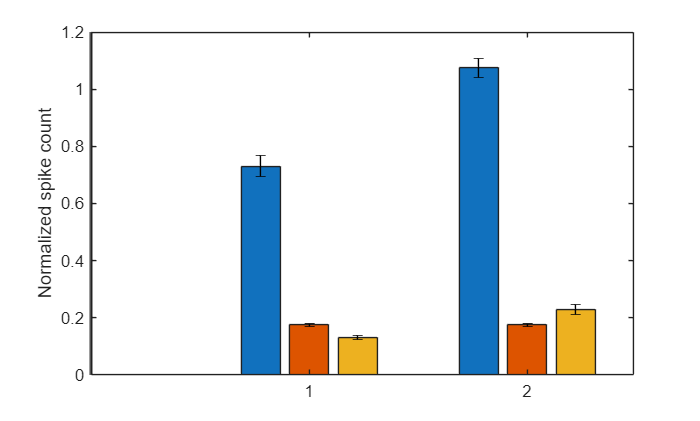

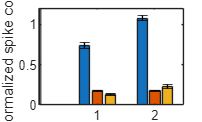


% er = errorbar(y, y_err);
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';

% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(y);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:nbars
    x(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',y,y_err,'k','linestyle','none');

hold off

 p_dev = anova1([DEV_R, DEV_P])
% 
 p_std = anova1([STD_R, STD_P])

p_dev_ctr = anova1([DEV_R, CTR_R])
p_dev_std = anova1([DEV_R, STD_R])
p_ctr_std = anova1([CTR_R, STD_R])

p_dev_ctrP = anova1([DEV_P, CTR_P])
p_dev_stdP = anova1([DEV_P, STD_P])
p_ctr_stdP = anova1([CTR_P, STD_P])
% 
% p_dev = friedman(DEV_R,6)
% 
% p_ctr = friedman(CTR_R,6)
% 
% p_std = friedman(STD_R,6)

[p_DEV_w,h_DEV_w] = ranksum(DEV_R, DEV_P)
[p_STD_w,h_STD_w] = ranksum(STD_R, STD_P)

[p_DEV_w,h_DEV_w] = ranksum(DEV_R, CTR_R)
[p_DEV_w,h_DEV_w] = ranksum(DEV_R, STD_R)
[p_CTR_w,h_CTR_w] = ranksum(CTR_R, STD_R)

[p_DEV_w,h_DEV_w] = ranksum(DEV_P, CTR_P)
[p_DEV_w,h_DEV_w] = ranksum(DEV_P, STD_P)
[p_CTR_w,h_CTR_w] = ranksum(CTR_P, STD_P)


cd 'D:\V1_Cortex_Paper\MultichannelDataTanks\Bra Graph';
saveas(gcf,'R_P_err_L5.pdf');
saveas(gcf,'R_P_err_L5.tif');
saveas(gcf,'R_P_err_L5.fig');

DEV_R = [Layer6_Sig.DEV1;Layer6_Sig.DEV2];
STD_R = [Layer6_Sig.STD1;Layer6_Sig.STD2];
CTR_R = [Layer6_Sig.CTR1MS;Layer6_Sig.CTR2MS];

DEV_P = [Layer6_Sig.NormDEVPms1;Layer6_Sig.NormDEVPms2];
STD_P = [Layer6_Sig.NormSTDPms1;Layer6_Sig.NormSTDPms2];
CTR_P = [Layer6_Sig.CTR1MS;Layer6_Sig.CTR2MS];

y_R = [DEV_R, CTR_R, STD_R];
y_P = [DEV_P, CTR_P, STD_P];


y_mR = mean(y_R,'omitnan') 

y_mR =     0.7862    0.1693    0.2149




y_mP = mean(y_P,'omitnan')

y_mP =     1.0890    0.1693    0.2301




y = [y_mR; y_mP];
y = [y_mR; y_mP];
b = bar(y, 'grouped');
ylim([0 1.2]);

hold on
xline(0,'LineWidth',2);
ylabel('Normalized spike count')

RNDEV_std = std(y_R(:,1),'omitnan');
err_RNDEV = RNDEV_std / sqrt(size(y_R(:,1),1))

err_RNDEV = 0.0215


RNCTR_std = std(y_R(:,2),'omitnan');
err_RNCTR = RNCTR_std / sqrt(size(y_R(:,2),1))

err_RNCTR = 0.0043


RNSTD_std = std(y_R(:,3),'omitnan');
err_RNSTD = RNSTD_std / sqrt(size(y_R(:,3),1))

err_RNSTD = 0.0289


PNDEV_std = std(y_P(:,1),'omitnan');
err_PNDEV = PNDEV_std / sqrt(size(y_P(:,1),1))

err_PNDEV = 0.0153


PNCTR_std = std(y_P(:,2),'omitnan');
err_PNCTR = PNCTR_std / sqrt(size(y_P(:,2),1))

err_PNCTR = 0.0043


PNSTD_std = std(y_P(:,3),'omitnan');
err_PNSTD = PNSTD_std / sqrt(size(y_P(:,3),1))

err_PNSTD = 0.0209


y_mRerr = [err_RNDEV err_RNCTR err_RNSTD]

y_mRerr =     0.0215    0.0043    0.0289


y_mPerr = [err_PNDEV  err_PNCTR err_PNSTD]

y_mPerr =     0.0153    0.0043    0.0209



y_err = [y_mRerr; y_mPerr]

y_err =     0.0215    0.0043    0.0289
    0.0153    0.0043    0.0209



% er = errorbar(y, y_err);
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';

% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(y);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:nbars
    x(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',y,y_err,'k','linestyle','none');

hold off
 p_dev = anova1([DEV_R, DEV_P])
% 
 p_std = anova1([STD_R, STD_P])

p_dev_ctr = anova1([DEV_R, CTR_R])
p_dev_std = anova1([DEV_R, STD_R])
p_ctr_std = anova1([CTR_R, STD_R])

p_dev_ctrP = anova1([DEV_P, CTR_P])
p_dev_stdP = anova1([DEV_P, STD_P])
p_ctr_stdP = anova1([CTR_P, STD_P])
% % 
% p_dev = friedman(DEV_R,6)
% 
% p_ctr = friedman(CTR_R,6)
% 
% p_std = friedman(STD_R,6)

[p_DEV_w,h_DEV_w] = ranksum(DEV_R, DEV_P)
[p_STD_w,h_STD_w] = ranksum(STD_R, STD_P)

[p_DEV_w,h_DEV_w] = ranksum(DEV_R, CTR_R)
[p_DEV_w,h_DEV_w] = ranksum(DEV_R, STD_R)
[p_CTR_w,h_CTR_w] = ranksum(CTR_R, STD_R)

[p_DEV_w,h_DEV_w] = ranksum(DEV_P, CTR_P)
[p_DEV_w,h_DEV_w] = ranksum(DEV_P, STD_P)
[p_CTR_w,h_CTR_w] = ranksum(CTR_P, STD_P)


cd 'D:\V1_Cortex_Paper\MultichannelDataTanks\Bra Graph';
saveas(gcf,'R_P_err_L6.pdf');
saveas(gcf,'R_P_err_L6.tif');
saveas(gcf,'R_P_err_L6.fig');